# Plot Figure 4 and Figure S14

## Set up path

addpath(genpath('../public_code'))

nNodes = 9


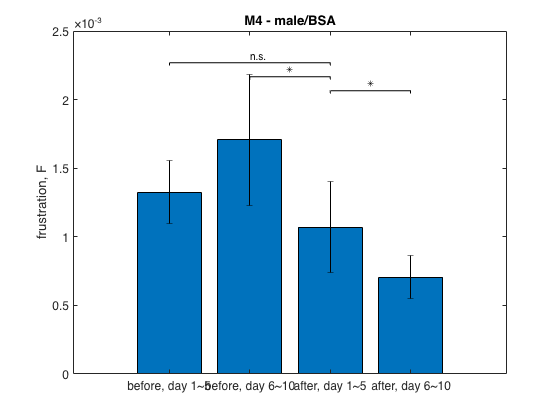

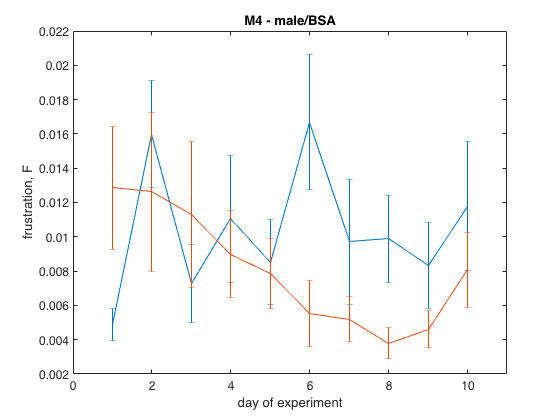

P-value for each day = 
    0.2518    0.2731    0.4040    0.3499    0.2423    0.0912    0.0786    0.0364    0.0576    0.2629


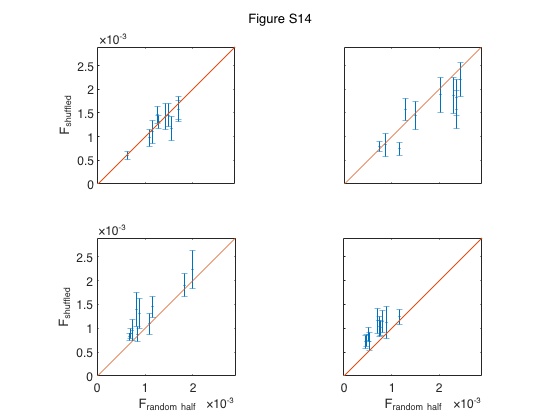

%% Make plots: Figure 4B, 4C, S14
plot_figure4('male_bsa');

nNodes = 15


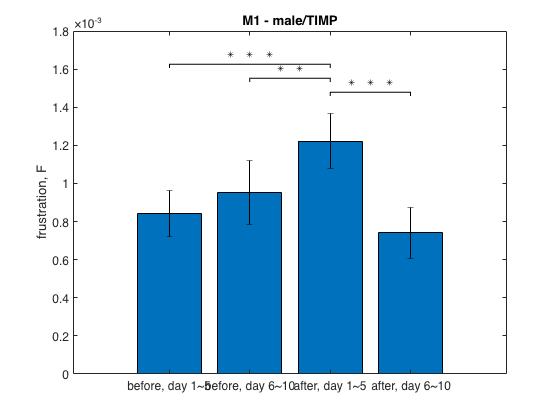

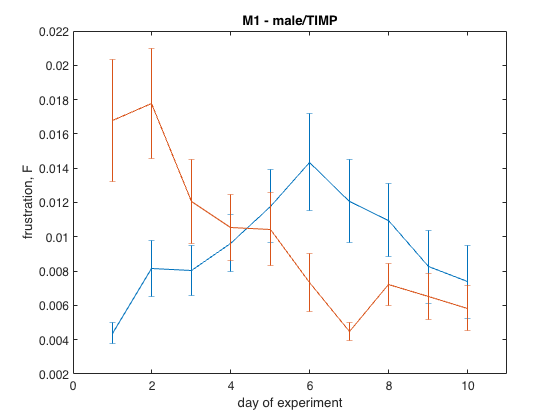

P-value for each day = 
    0.0054    0.0019    0.1852    0.3599    0.3725    0.2255    0.0403    0.2118    0.1501    0.0996


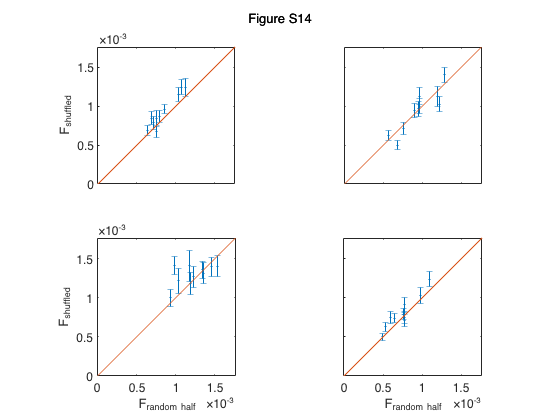

plot_figure4('male_timp');

nNodes = 13


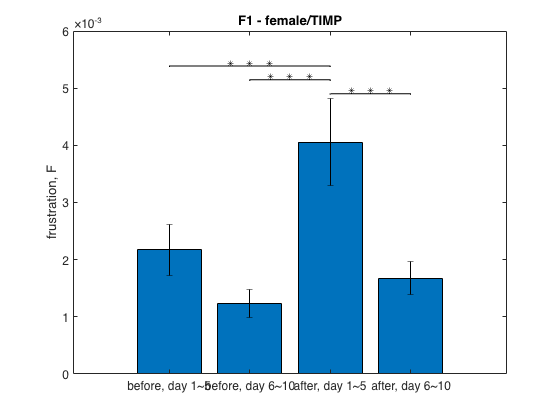

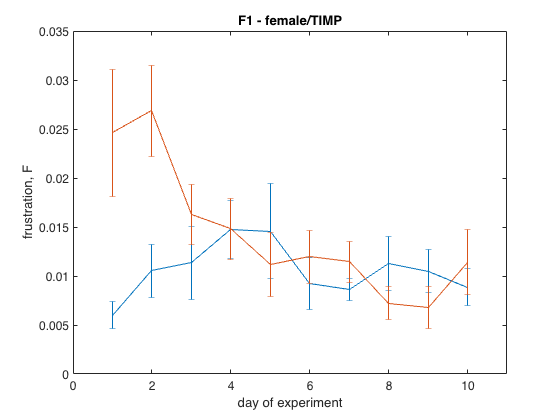

P-value for each day = 
    0.0000    0.0000    0.0158    0.0564    0.4145    0.3032    0.3712    0.1042    0.0778    0.3773


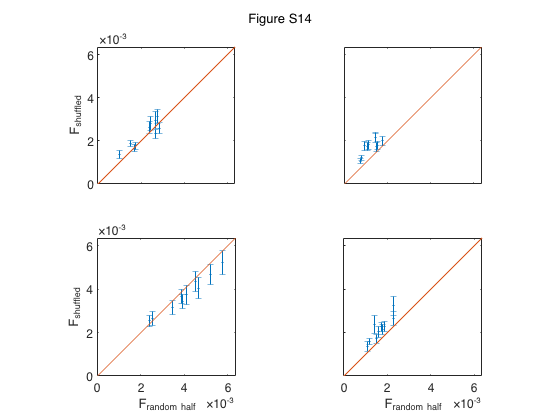

plot_figure4('female_timp');

function plot_figure4(nstrain)

[nstrain_before, nstrain_after, nstrain_title, nNodes] = load_data_figure4(nstrain);
nEdges = nNodes * (nNodes - 1) / 2;

%% load learned SME params


[jij_f5bt, hir_f5bt] = load_sme_params_5days...
    (nstrain_before, 'first', nNodes, 'gd');
mjij_f5bt = mean(jij_f5bt,2);

[jij_l5bt, hir_l5bt] = load_sme_params_5days...
    (nstrain_before, 'last', nNodes, 'gd');
mjij_l5bt = mean(jij_l5bt,2);

[jij_f5at, hir_f5at] = load_sme_params_5days...
    (nstrain_after, 'first', nNodes, 'gd');
mjij_f5at = mean(jij_f5at,2);


[jij_l5at, hir_l5at] = load_sme_params_5days...
    (nstrain_after, 'last', nNodes, 'gd');
mjij_l5at = mean(jij_l5at,2);

%% compute frustration

frus_f5bt_bs = compute_frustration_bs(jij_f5bt, nNodes);
frus_l5bt_bs = compute_frustration_bs(jij_l5bt, nNodes);
frus_f5at_bs = compute_frustration_bs(jij_f5at, nNodes);
frus_l5at_bs = compute_frustration_bs(jij_l5at, nNodes);
frus_master = [frus_f5bt_bs', frus_l5bt_bs', ...
               frus_f5at_bs', frus_l5at_bs'];

%% compute significance test for equal frustration (equal mean)
pMat = nan(4);
pMat(1,2) = welch_ttest_randomhalves(frus_f5bt_bs, frus_l5bt_bs);
pMat(1,3) = welch_ttest_randomhalves(frus_f5bt_bs, frus_f5at_bs);
pMat(1,4) = welch_ttest_randomhalves(frus_f5bt_bs, frus_l5at_bs);
pMat(2,3) = welch_ttest_randomhalves(frus_l5bt_bs, frus_f5at_bs);
pMat(2,4) = welch_ttest_randomhalves(frus_l5bt_bs, frus_l5at_bs);
pMat(3,4) = welch_ttest_randomhalves(frus_f5at_bs, frus_l5at_bs);
sigMat = (pMat < 0.025/6) + (pMat < 0.01/2/6) + (pMat < 0.001/2/6);


%% make plots
figure()
bar(mean(frus_master))
hold on
errorbar(mean(frus_master), std(frus_master)/sqrt(2),'k.')
hold off
xticks([1,2,3,4])
xticklabels({'before, day 1~5',...
    'before, day 6~10',...
    'after, day 1~5',...
    'after, day 6~10'})
set(gca,'fontsize',12)
ylabel('frustration, F')
title(nstrain_title)

hold on

edgeList = [1,2; 3,4; 2,3; 1,3; 2,4; 1,4];

count = 1;
for iedge = 1:6
    my_edge = edgeList(iedge,:);
    i = my_edge(1);
    j = my_edge(2);

    if (i == 1 && j == 3) || (i == 2 && j == 3) || (i == 3 && j == 4)
%     if sigMat(i,j) > 0
        plot([i,j], [1 1]*max(mean(frus_master))*(1.15 + 0.06*count), '-k', 'LineWidth',1)
        plot([i,i],...
            [1 1]*max(mean(frus_master))*(1.15 + 0.06*count)-...
            [0.00002,-0.000002],'-k', 'LineWidth',1)
        plot([j,j],...
            [1 1]*max(mean(frus_master))*(1.15 + 0.06*count)-...
            [0.00002,-0.000002],'-k', 'LineWidth',1)
        if sigMat(i,j) == 1
            plot((i+j)/2, max(mean(frus_master))*(1.15 + 0.06*count)+0.00005,...
                '*k')
        elseif sigMat(i,j) == 2
            plot((i+j)/2+[-0.12, 0.12], [1,1]*max(mean(frus_master))*(1.15 + 0.06*count)+0.00005,...
                '*k')
        elseif sigMat(i,j) == 3
            plot((i+j)/2+[-0.24, 0, 0.24], [1,1,1]*max(mean(frus_master))*(1.15 + 0.06*count)+0.00005,...
                '*k')
        else
            text((i+j)/2, max(mean(frus_master))*(1.15 + 0.06*count)+0.00005,...
                'n.s.')
        end

        count = count + 1;
    end
end

hold off

%% make plots: frustration every single day

method = 'gd';
[jij3_before, hir3_before] = load_sme_params(nstrain_before, nNodes, method);
frus_bs_ndays_before = compute_frustration_bs_ndays(jij3_before, nNodes);
[jij3_after, hir3_after] = load_sme_params(nstrain_after, nNodes, method);
frus_bs_ndays_after = compute_frustration_bs_ndays(jij3_after, nNodes);

figure()
errorbar(mean(frus_bs_ndays_before,2), std(frus_bs_ndays_before,0,2)/sqrt(2))
hold on
errorbar(mean(frus_bs_ndays_after,2), std(frus_bs_ndays_after,0,2)/sqrt(2))
hold off
set(gca,'fontsize',12)
ylabel('frustration, F')
xlabel('day of experiment')
title(nstrain_title)
xlim([0 11])

%% Compute p-value for single-day 10-day longitudinal tests



nDays = 10;
p2_frus = zeros(1,nDays);
for iday = 1:nDays
    p2_frus(iday) = sig_test_single_day(frus_bs_ndays_before, ...
        frus_bs_ndays_after(iday,:));
end

disp('P-value for each day = ')
disp(p2_frus);


[~, frus_f5bt_bs_shuffle] = compute_shuffled_frustration_bs(jij_f5bt, nNodes);
[~, frus_l5bt_bs_shuffle] = compute_shuffled_frustration_bs(jij_l5bt, nNodes);
[~, frus_f5at_bs_shuffle] = compute_shuffled_frustration_bs(jij_f5at, nNodes);
[~, frus_l5at_bs_shuffle] = compute_shuffled_frustration_bs(jij_l5at, nNodes);


frus_shuffle_master3 = cat(3, frus_f5bt_bs_shuffle,...
    frus_l5bt_bs_shuffle,  frus_f5at_bs_shuffle, ...
    frus_l5at_bs_shuffle);



%% plot frustration against shuffled frustration (Figure S14)

figure()


for idata = 1:4
    subplot(2,2,idata)
    errorbar(frus_master(:,idata), ...
        mean(frus_shuffle_master3(:,:,idata)), ...
        std(frus_shuffle_master3(:,:,idata)), '.');
    hold on
    plot([0 1],[0 1],'-')
     axis([0 1.1 0 1.1]*max(max(frus_master(:)), ...
        max(max(mean(frus_shuffle_master3) + ...
        std(frus_shuffle_master3)))));
    hold off
    axis square
    set(gca,'fontsize',12)
    ylabel('F_{shuffled}')
    xlabel('F_{random half}')

end

%
subplot(2,2,1)
xlabel('')
xticklabels('')

subplot(2,2,2)
ylabel('')
xlabel('')
xticklabels('')
yticklabels('')

subplot(2,2,4)
ylabel('')
yticklabels('')

sgtitle('Figure S14')

end


function [nstrain_before, nstrain_after, nstrain_title, nNodes] = load_data_figure4(nstrain)


switch nstrain
    case 'male_timp'
        nstrain_before = 'male_before_timp_180511';
        nstrain_after = 'male_after_timp_180526'; nNodes = 15;
        nstrain_title = 'M1 - male/TIMP';
    case 'male_bsa'
        nstrain_before = 'male_before_bsa_200713'; 
        nstrain_after = 'male_after_bsa_200727'; nNodes = 9 ; %10;
        nstrain_title = 'M4 - male/BSA';
    case 'female_timp'
        nstrain_before = 'female_before_timp_180413';
%         nstrain_after = 'female_after_timp_180430_nomouse13'; 

        nstrain_after = 'female_after_timp_180430'; 
        nNodes = 13; % after removing mouse 13, nNodes becomes 13, was 14
        nstrain_title = 'F1 - female/TIMP';
    otherwise
        error('Wrong strain name. Choose between male_timp, male_bsa, or female_timp.')
end

disp(['nNodes = ' num2str(nNodes)])


end

function [jij2, hir2] = load_sme_params_5days(nstrain, n5days, nNodes, method)
%n5days = 'first' or 'last'

%%
nStates = 4;

tp = '~/MyDocuments/biophysics/projects/social_mice/output/';

nbs = 10;
jij2 = nan(nNodes*(nNodes-1)/2, nbs);
hir2 = nan(nNodes*(nStates-1), nbs);


for ibs = 1:nbs
    if strcmp(nstrain, 'female_before_timp_180413') || ...
        strcmp(nstrain, 'female_after_timp_180430') || ...
        strcmp(nstrain, 'male_before_bsa_200713') || ...
        strcmp(nstrain, 'male_after_bsa_200727') 
        fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' nstrain ...
                '_nim_' n5days '5days_ibs' num2str(ibs) '.mat'];
    else
        fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' nstrain ...
                '_' n5days '5days_ibs' num2str(ibs) '.mat'];
    end


    switch method
        case 'gd'
            load(fp, 'jij_gd_eachday', 'hir_gd_eachday');
            jij2(:, ibs) = jij_gd_eachday;
            hir2(:, ibs) = hir_gd_eachday;
        case 'l1'
            load(fp, 'jij_l1_eachday', 'hir_l1_eachday');
            jij2(:, ibs) = jij_l1_eachday;
            hir2(:, ibs) = hir_l1_eachday;
    end
end
end

%%

% load learned parameters from the static Maximum Entropy models
function [jij2, hir2] = load_sme_params(nstrain, nNodes, method)

%%
nStates = 4;

tp = '~/MyDocuments/biophysics/projects/social_mice/output/';

nbs = 10;
nDays = 10;
jij2 = nan(nNodes*(nNodes-1)/2, nDays, nbs);
hir2 = nan(nNodes*(nStates-1), nDays, nbs);


for dayId = 0:nDays-1
    for ibs = 1:nbs
        if strcmp(nstrain, 'female_before_timp_180413') || ...
            strcmp(nstrain, 'female_after_timp_180430') || ...
            strcmp(nstrain, 'male_before_bsa_200713') || ...
            strcmp(nstrain, 'male_after_bsa_200727') 
            fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
                nstrain '_nim_iday' num2str(dayId+1) ...
                '_ibs' num2str(ibs) '.mat']; % nim = no inactive mice
%             fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
%                 nstrain '_iday' num2str(dayId+1) ...
%                 '_ibs' num2str(ibs) '.mat'];
        else
            fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
                nstrain '_iday' num2str(dayId+1) ...
                '_ibs' num2str(ibs) '.mat'];
        end


        switch method
            case 'gd'
                load(fp, 'jij_gd_eachday', 'hir_gd_eachday');
                jij2(:, dayId+1, ibs) = jij_gd_eachday;
                hir2(:, dayId+1, ibs) = hir_gd_eachday;
            case 'l1'
                load(fp, 'jij_l1_eachday', 'hir_l1_eachday');
                jij2(:, dayId+1, ibs) = jij_l1_eachday;
                hir2(:, dayId+1, ibs) = hir_l1_eachday;
        end
    end
end

end


function [pvalue] = welch_ttest_randomhalves(x1, x2)

%%
n1 = length(x1);
n2 = length(x2);
ss1 = var(x1)/2; % /2 is the correction , ss = s squared
ss2 = var(x2)/2;


t = (mean(x1) - mean(x2)) / sqrt(ss1/n1 + ss2/n2); 
dof = (ss1/n1 + ss2/n2)^2 / ( (ss1/n1)^2/(n1-1)  + (ss2/n2)^2/(n2-1) );

pvalue = tcdf(t, dof);
if pvalue > 0.5
    pvalue = 1 - pvalue;
end


end

function [frus_bs_ndays] = compute_frustration_bs_ndays(jij3, nNodes)

ndays = size(jij3, 2);
nbs = size(jij3, 3);
frus_bs_ndays = nan(ndays, nbs);
for iday = 1:ndays
    for ibs = 1:nbs
        %%
        my_jij = jij3(:, iday, ibs);
        my_jijMat = recoverUpt(my_jij, nNodes);
        frus2 = compute_frustration_from_jijmat(my_jijMat);
        my_frus = -mean(frus2(1,frus2(2,:)==2));
        frus_bs_ndays(iday, ibs) = my_frus;
    end
end

end


function [frus_bs] = compute_frustration_bs(jij2, nNodes)

nbs = size(jij2,2);
frus_bs = nan(1, nbs);
for ibs = 1:nbs
    %%
    my_jij = jij2(:,ibs);
    my_jijMat = recoverUpt(my_jij, nNodes);
    frus2 = compute_frustration_from_jijmat(my_jijMat);
    my_frus = -mean(frus2(1,frus2(2,:)==2));
    frus_bs(ibs) = my_frus;
end

end


function [frus_shuffle_bs_flat, frus_shuffle_bs] = ...
    compute_shuffled_frustration_bs(jij2, nNodes)

nbs = size(jij2,2);
nshuffle = 20;
frus_bs = nan(nshuffle, nbs);
for ibs = 1:nbs
    %%
    my_jij = jij2(:,ibs);
    for ishuffle = 1:nshuffle
        kk = randperm(nNodes*(nNodes-1)/2);
        jij_shuffle = my_jij(kk);
        my_jijMat = recoverUpt(jij_shuffle, nNodes);
        frus2 = compute_frustration_from_jijmat(my_jijMat);
        my_frus = -mean(frus2(1,frus2(2,:)==2));
        frus_shuffle_bs(ishuffle, ibs) = my_frus;
    end
end
frus_shuffle_bs_flat = reshape(frus_shuffle_bs, 1, nbs*nshuffle);

end

function [frus2] = compute_frustration_from_jijmat(jijMat)

nNodes = size(jijMat,1);

frus2 = zeros(2,nNodes*(nNodes-1)*(nNodes-2)/6);
    
count = 1;
for i = 1:nNodes
    for j = i+1:nNodes
        for k = j+1:nNodes
            frus2(1,count) = ...
                jijMat(i,j) * jijMat(j,k) * jijMat(i,k);
            frus2(2,count) = ...
                (jijMat(i,j)>0) + (jijMat(j,k)>0) + (jijMat(i,k)>0);
            count = count+1;
        end
    end
end


end



function [p] = sig_test_single_day(q2_base, q_test)


%%
q_base_mean = mean(mean(q2_base,2));
q_base_std = std(mean(q2_base,2));

p = normcdf(mean(q_test), q_base_mean, q_base_std);
if p > 0.5
    p = 1-p;
end

end
